clear
close all

spring = xlsread('nuts_env2_d1.xlsx');



%%Defining variables: OJO Matlab no lee la primera fila que es texto, si quiero
%%hay funciones para hacerlo. EQUIDISTANCIA(0,207)
lon = spring (:,3);
lonint = [linspace(min(lon),max(lon),20)];   %malla para lonitud que vaya del min al max equidistantement
depth = spring (:,5);
presint = (1:5:200); presint = presint';  %crea matriz interpolada para ver toda la malla de profundidades desde 0 a 200m (dentro de capa f�tica) que es el max de 1 en 1, y quiero que se repita de manera equidistante desde min lon a max lon

no2 = spring (:, 6);
no3 = spring(:,7);
nh4 = spring (:, 8);
TIN = spring (:, 9);
po4  = spring(:,10);
sio2 = spring(:,11);
Chla_3um = spring(:,12);
Chla_2um = spring(:,13);
chla_total = spring(:,14);

%separo los datos de cada estacion
idx_st3=find(spring(:,2)==3); %indice que indica qué filas pertenecen a la estación 3
data_st3=spring(idx_st3,:);
idx_st4=find(spring(:,2)==4); %indice que indica qué filas pertenecen a la estación 4
data_st4=spring(idx_st4,:);
idx_st5=find(spring(:,2)==5); %indice que indica qué filas pertenecen a la estación 5
data_st5=spring(idx_st5,:);
idx_st6=find(spring(:,2)==6); %indice que indica qué filas pertenecen a la estación 6
data_st6=spring(idx_st6,:);

## variables por estación

% Estación 3
depth_st3 = data_st3(:,5);
NO2_st3 = data_st3(:, 6);
no3_st3 = data_st3(:,7);
nh4_st3 = data_st3(:, 8);
TIN_st3 = data_st3(:, 9);
po4_st3  = data_st3(:, 10);
sio2_st3 = data_st3(:, 11);
Chla_3um_st3 = data_st3(:, 12);
Chla_2um_st3 = data_st3(:, 13);
chla_total_st3 = data_st3(:, 14);

% Estación 4
depth_st4 = data_st4(:,5);
NO2_st4 = data_st4(:, 6);
no3_st4 = data_st4(:,7);
nh4_st4 = data_st4(:, 8);
TIN_st4 = data_st4(:, 9);
po4_st4  = data_st3(:, 10);
sio2_st4 = data_st3(:, 11);
Chla_3um_st4 = data_st3(:, 12);
Chla_2um_st4 = data_st3(:, 13);
chla_total_st4 = data_st3(:, 14);

% Estación 5
depth_st5 = data_st5(:,5);
NO2_st5 = data_st5(:, 6);
no3_st5 = data_st5(:,7);
nh4_st5 = data_st5(:, 8);
TIN_st5 = data_st5(:, 9);
po4_st5  = data_st3(:, 10);
sio2_st5 = data_st3(:, 11);
Chla_3um_st5 = data_st3(:, 12);
Chla_2um_st5 = data_st3(:, 13);
chla_total_st5 = data_st3(:, 14);

% Estación 6
depth_st6 = data_st6(:,5);
NO2_st6 = data_st6(:, 6);
no3_st6 = data_st6(:,7);
nh4_st6 = data_st6(:, 8);
TIN_st6 = data_st6(:, 9);
po4_st6  = data_st3(:, 10);
sio2_st6 = data_st3(:, 11);
Chla_3um_st6 = data_st3(:, 12);
Chla_2um_st6 = data_st3(:, 13);
chla_total_st6 = data_st3(:, 14);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%5
% Aqui estaba el proceso para calcular el promedio que he borrado por que
% no nos interesa hacer promedio, los dias son muy diferentes en el verano.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

vuelvo a crear la variable TIN con sus profundidades asociadas

## TIN %%%

TIN_mean=[TIN_st3;TIN_st4;TIN_st5;TIN_st6];
NO2_mean=[NO2_st3;NO2_st4;NO2_st5;NO2_st6];
no3_mean=[no3_st3;no3_st4;no3_st5;no3_st6];
nh4_mean=[nh4_st3;nh4_st4;nh4_st5;nh4_st6];
po4_mean=[po4_st3;po4_st4;po4_st5;po4_st6];
sio2_mean=[sio2_st3;sio2_st4;sio2_st5;sio2_st6];
chla_total_mean=[chla_total_st3;chla_total_st4;chla_total_st5;chla_total_st6];

depth_mean=[depth_st3;depth_st4;depth_st5;depth_st6];
lon_mean=[repelem(8.956,5) repelem(9.207,5) repelem(9.408,5) repelem(9.608,5)];

malla de colores para fluo

[x,y]= meshgrid(lonint,presint);

%INTERPOlo mis variables sobre la malla x,y que acabo de crear
TINint= griddata(lon_mean(isfinite(TIN_mean)),depth_mean(isfinite(TIN_mean)),TIN_mean(isfinite(TIN_mean)),x(1,:),y(:,1));
NO2int= griddata(lon_mean(isfinite(NO2_mean)),depth_mean(isfinite(NO2_mean)),NO2_mean(isfinite(NO2_mean)),x(1,:),y(:,1));
no3int= griddata(lon_mean(isfinite(no3_mean)),depth_mean(isfinite(no3_mean)),no3_mean(isfinite(no3_mean)),x(1,:),y(:,1));
nh4int= griddata(lon_mean(isfinite(nh4_mean)),depth_mean(isfinite(nh4_mean)),nh4_mean(isfinite(nh4_mean)),x(1,:),y(:,1));
po4int= griddata(lon_mean(isfinite(po4_mean)),depth_mean(isfinite(po4_mean)),po4_mean(isfinite(po4_mean)),x(1,:),y(:,1));
sio2int= griddata(lon_mean(isfinite(sio2_mean)),depth_mean(isfinite(sio2_mean)),sio2_mean(isfinite(sio2_mean)),x(1,:),y(:,1));
chla_totalint= griddata(lon_mean(isfinite(chla_total_mean)),depth_mean(isfinite(chla_total_mean)),chla_total_mean(isfinite(chla_total_mean)),x(1,:),y(:,1));


%OJO que la funcion pcolor por defecto elimina el ultimo perfil, se podria
%repetir ese ultimo pefil para solventar
TINint = [TINint,TINint(:,end)];
NO2int = [NO2int,NO2int(:,end)];
no3int = [no3int,no3int(:,end)];
nh4int = [nh4int,nh4int(:,end)];
po4int = [po4int,po4int(:,end)];
sio2int = [sio2int,sio2int(:,end)];
chla_totalint = [chla_totalint,chla_totalint(:,end)];


lonint=[lonint,lonint(:,end)+0.05];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%    Figuras 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Las figuras estan hechas con la funcion "contourf" y "scatter" para comparar
% la interpolacion (conturf = interpolacion VS scatter = datos reales)

## NO2 %%%

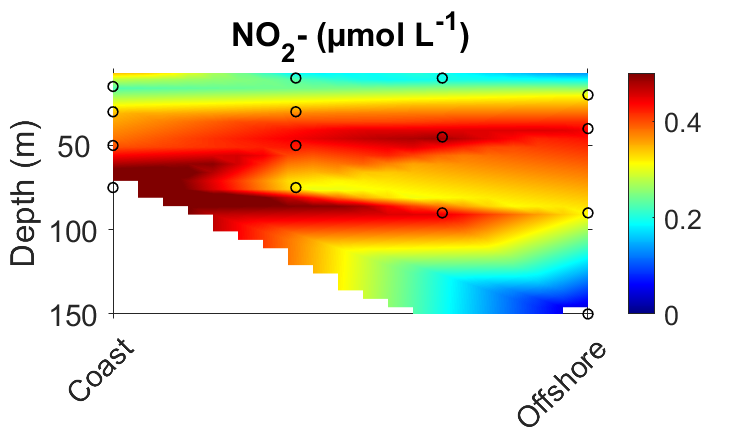

figure()

xSize=12;
ySize=7;
xLeft=(12-xSize)/2;
yTop=(7-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]); %get current figure con fondo blanco
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

% % lonint=lonint';


pcolor(lonint, -presint, NO2int); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd')

colormap('jet');
cb=colorbar;
caxis([0 .5]); 

%nombre a los ejes y etiquetas (numeritos)
xlabel('','FontWeight','normal','fontsize',22);
ylabel('','FontWeight','normal','fontsize',12);
set(gca,'tickdir','out','Xtick',[8.956 9.608],'Xticklabel',[{ 'Coast'  'Offshore' }],'Ytick',[-150 -100 -50 0],'Yticklabel',[150 100 50 0],'fontsize',18);
xtickangle(45)

hold on; %marcamos los puntos de muestreo:
scatter(lon_mean(isfinite(NO2_mean)),-depth_mean(isfinite(NO2_mean)),35,'o','filled','MarkerFaceColor','none','MarkerEdgeColor','k','LineWidth',1);

title('NO_{2}^ - (µmol L^-^1)')
xlim([8.956 9.608])
ylim([-150 -7])
ylabel('Depth (m)','fontsize',20)

exportgraphics(gcf, 'spring_NO2.png','Resolution',300)

## NO3 %%%

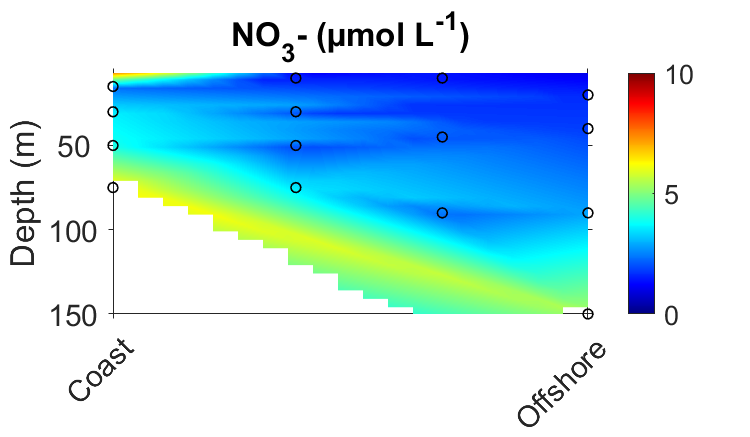

figure()

xSize=12;
ySize=7;
xLeft=(12-xSize)/2;
yTop=(7-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]); %get current figure con fondo blanco
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

lonint=lonint';

pcolor(lonint, -presint, no3int); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd')

colormap('jet');
cb=colorbar;
caxis([0 10]); 

%nombre a los ejes y etiquetas (numeritos)
xlabel('','FontWeight','normal','fontsize',22);
ylabel('','FontWeight','normal','fontsize',16);
set(gca,'tickdir','out','Xtick',[8.956 9.608],'Xticklabel',[{ 'Coast'  'Offshore' }],'Ytick',[-150 -100 -50 0],'Yticklabel',[150 100 50 0],'fontsize',18);
xtickangle(45)

hold on; %marcamos los puntos de muestreo:
scatter(lon_mean(isfinite(no3_mean)),-depth_mean(isfinite(no3_mean)),35,'o','filled','MarkerFaceColor','none','MarkerEdgeColor','k','LineWidth',1);

% Ajustamos los limites de lat y prof
title('NO_{3}^ - (µmol L^-^1)')
xlim([8.956 9.608])
ylim([-150 -7])
ylabel('Depth (m)','fontsize',20)

exportgraphics(gcf, 'spring_NO3.png','Resolution',300)

## NH4 %%

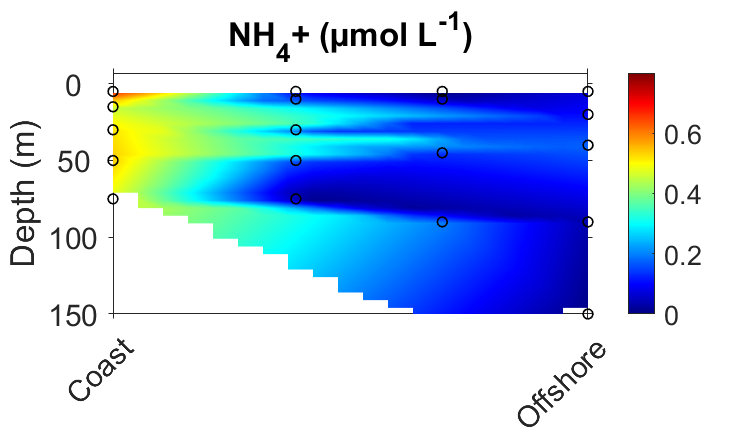

figure()

xSize=12;
ySize=7;
xLeft=(12-xSize)/2;
yTop=(7-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]); %get current figure con fondo blanco
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

lonint=lonint';

pcolor(lonint, -presint, nh4int); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd')

colormap('jet');
cb=colorbar;
caxis([0 0.8]); 

%nombre a los ejes y etiquetas (numeritos)
xlabel('','FontWeight','normal','fontsize',22);
ylabel('','FontWeight','normal','fontsize',22);
set(gca,'tickdir','out','Xtick',[8.956 9.608],'Xticklabel',[{ 'Coast'  'Offshore' }],'Ytick',[-150 -100 -50 0],'Yticklabel',[150 100 50 0],'fontsize',18);
xtickangle(45)

hold on; %marcamos los puntos de muestreo:
scatter(lon_mean(isfinite(nh4_mean)),-depth_mean(isfinite(nh4_mean)),35,'o','filled','MarkerFaceColor','none','MarkerEdgeColor','k','LineWidth',1);


% Ajustamos los limites de lat y prof
title('NH_{4}^ + (µmol L^-^1)')
xlim([8.956 9.608])
ylim([-150 7])
ylabel('Depth (m)','fontsize',20)

exportgraphics(gcf, 'spring_NH4.png','Resolution',300)

## TIN %%%

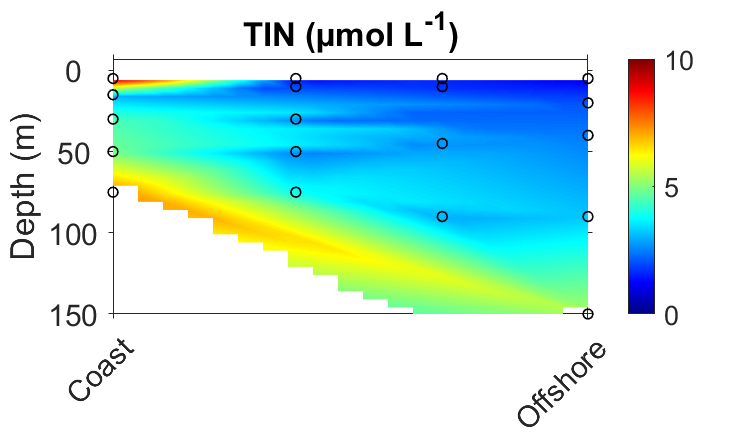

figure()

xSize=12;
ySize=7;
xLeft=(12-xSize)/2;
yTop=(7-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]); %get current figure con fondo blanco
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

lonint=lonint';

pcolor(lonint, -presint, TINint); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd')

colormap('jet');
cb=colorbar;
caxis([0 10]); 

%nombre a los ejes y etiquetas (numeritos)
xlabel('','FontWeight','normal','fontsize',22);
ylabel('','FontWeight','normal','fontsize',22);
set(gca,'tickdir','out','Xtick',[8.956 9.608],'Xticklabel',[{ 'Coast'  'Offshore' }],'Ytick',[-150 -100 -50 0],'Yticklabel',[150 100 50 0],'fontsize',18);
xtickangle(45)

hold on; %marcamos los puntos de muestreo:
scatter(lon_mean(isfinite(TIN_mean)),-depth_mean(isfinite(TIN_mean)),35,'o','filled','MarkerFaceColor','none','MarkerEdgeColor','k','LineWidth',1);

% Ajustamos los limites de lat y prof
title('TIN (µmol L^-^1)')
xlim([8.956 9.608])
ylim([-150 7])
ylabel('Depth (m)','fontsize',20)

exportgraphics(gcf, 'spring_TIN.png','Resolution',300)

## PO4 %%%

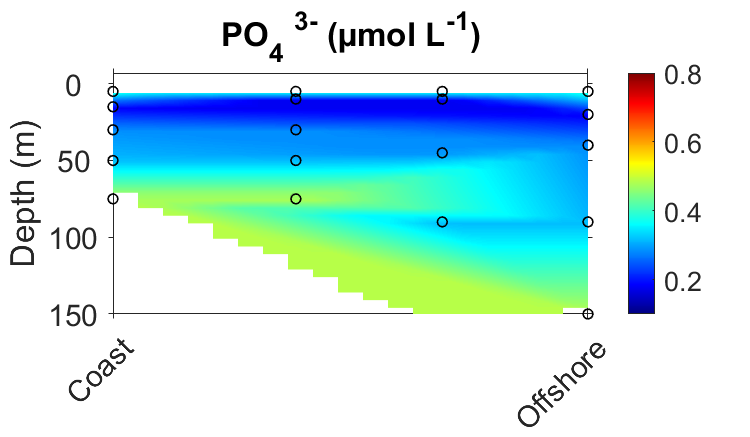

figure()

xSize=12;
ySize=7;
xLeft=(12-xSize)/2;
yTop=(7-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]); %get current figure con fondo blanco
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

lonint=lonint';

pcolor(lonint, -presint, po4int); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd')

colormap('jet');
cb=colorbar;
caxis([0.1 0.8]); 

%nombre a los ejes y etiquetas (numeritos)
xlabel('','FontWeight','normal','fontsize',22);
ylabel('','FontWeight','normal','fontsize',22);
set(gca,'tickdir','out','Xtick',[8.956 9.608],'Xticklabel',[{ 'Coast'  'Offshore' }],'Ytick',[-150 -100 -50 0],'Yticklabel',[150 100 50 0],'fontsize',18);
xtickangle(45)

hold on; %marcamos los puntos de muestreo:
scatter(lon_mean(isfinite(po4_mean)),-depth_mean(isfinite(po4_mean)),35,'o','filled','MarkerFaceColor','none','MarkerEdgeColor','k','LineWidth',1);

% Ajustamos los limites de lat y prof
title('PO_{4} ^3^- (µmol L^-^1)')
xlim([8.956 9.608])
ylim([-150 7])
ylabel('Depth (m)','fontsize',20)

exportgraphics(gcf, 'spring_PO4.png','Resolution',300)

## SiO2 %%%

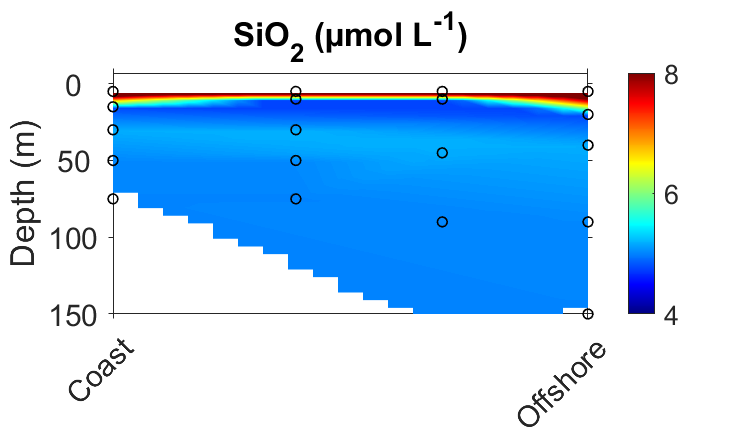

figure()

xSize=12;
ySize=7;
xLeft=(12-xSize)/2;
yTop=(7-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]); %get current figure con fondo blanco
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

lonint=lonint';

pcolor(lonint, -presint, sio2int); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd')

colormap('jet');
cb=colorbar;
caxis([4 8]); 

%nombre a los ejes y etiquetas (numeritos)
xlabel('','FontWeight','normal','fontsize',22);
ylabel('','FontWeight','normal','fontsize',22);
set(gca,'tickdir','out','Xtick',[8.956 9.608],'Xticklabel',[{ 'Coast'  'Offshore' }],'Ytick',[-150 -100 -50 0],'Yticklabel',[150 100 50 0],'fontsize',18);
xtickangle(45)

hold on; %marcamos los puntos de muestreo:
scatter(lon_mean(isfinite(sio2_mean)),-depth_mean(isfinite(sio2_mean)),35,'o','filled','MarkerFaceColor','none','MarkerEdgeColor','k','LineWidth',1);

% Ajustamos los limites de lat y prof
title('SiO_{2} (µmol L^-^1)')
xlim([8.956 9.608])
ylim([-150 7])
ylabel('Depth (m)','fontsize',20)

exportgraphics(gcf, 'spring_SiO2.png','Resolution',300)

## Chl-a Total %%%

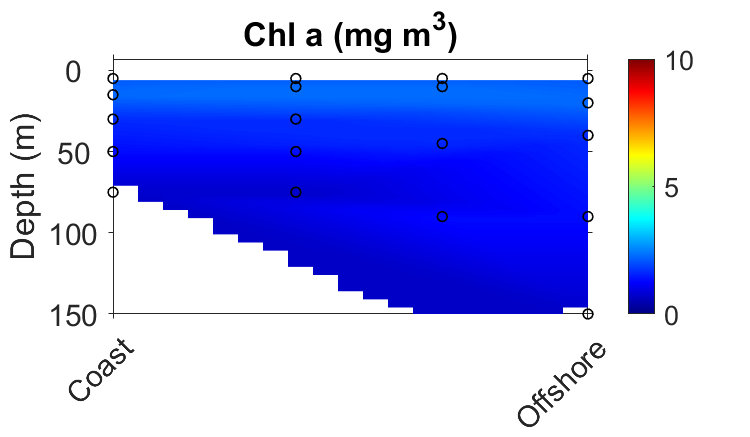

figure()

xSize=12;
ySize=7;
xLeft=(12-xSize)/2;
yTop=(7-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]); %get current figure con fondo blanco
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

lonint=lonint';

pcolor(lonint, -presint, chla_totalint); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd')

colormap('jet');
cb=colorbar;
caxis([0 10]); 


%nombre a los ejes y etiquetas (numeritos)
xlabel('','FontWeight','normal','fontsize',22);
ylabel('','FontWeight','normal','fontsize',22);
set(gca,'tickdir','out','Xtick',[8.956 9.608],'Xticklabel',[{ 'Coast'  'Offshore' }],'Ytick',[-150 -100 -50 0],'Yticklabel',[150 100 50 0],'fontsize',18);
xtickangle(45)

hold on; %marcamos los puntos de muestreo:
scatter(lon_mean(isfinite(chla_total_mean)),-depth_mean(isfinite(chla_total_mean)),35,'o','filled','MarkerFaceColor','none','MarkerEdgeColor','k','LineWidth',1);

% Ajustamos los limites de lat y prof
title('Chl a (mg m^3)')
xlim([8.956 9.608])
ylim([-150 7])
ylabel('Depth (m)','fontsize',20)

exportgraphics(gcf, 'spring_Chla.png','Resolution',300)